# Lab for The Statistical Paradigm

## Theoretical quantities describe a probability distribution.  Estimates of theoretical quantities from data are noisy and we must quantify the accuracy of our estimate.

To warm up, let's consider consider the least squares estimate for the statistical model $Y_i = f(x_i) + \epsilon_i$ with $f(x) = \beta_0 + \beta_1 x$.  Let's first consider the case where $\epsilon_i$ are distributed from the Normal probability distribution with mean $\mu=0$ and standard deviation $\sigma=1$:


$$\rho(x| \mu=0, \sigma=1) = \frac{1}{\sqrt{2\pi}}\exp(\frac{-x^2}{2})$$


which is the familiar "bell curve," pictured below

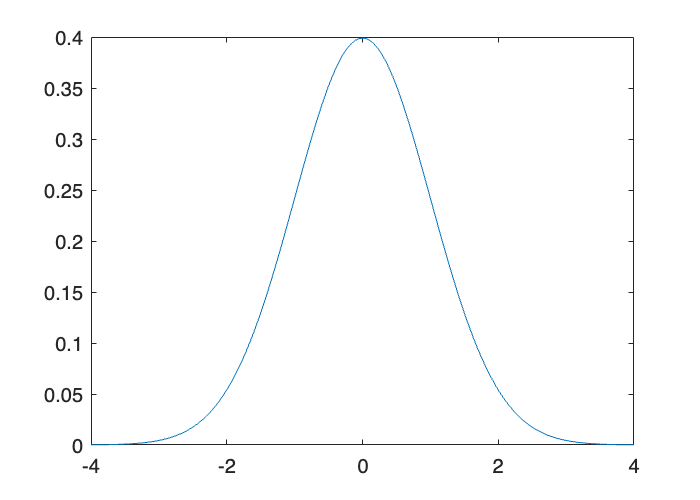

% define a set of x-values, obtain the corresponding values from the standard normal and plot
xNormal=-4:.05:4;
yNormal=normpdf(xNormal, 0, 1);
figure;
plot(xNormal, yNormal);
x0=10;
y0=10;
width=350;
height=250;
set(gcf,'units','points','position',[x0,y0,width,height])

Take $\beta_0=3$ and $\beta_1=5$, then we can generate a dataset from our statistical model, such as the one pictured below.  In black we plot the line y=3+5x, and in red we plot the line of best fit, in the least squares sense.

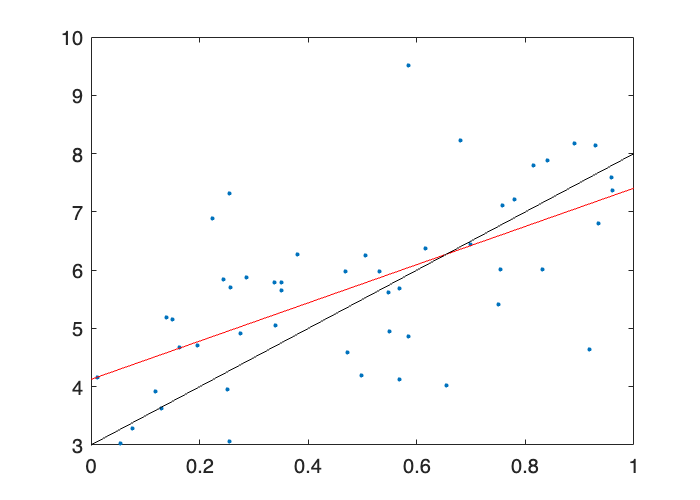

%obtain a random sample of, say, 50 datapoints from the statistical model, and plot
sizeDataSet=50;
%define beta values
betaNot=3;
betaOne=5;
%obtain noise
epsilonSample=randn(sizeDataSet,1);
%obtain x-values
xSample=rand(sizeDataSet, 1);
%obtain y-values: y=beta_0 + beta_1 x + noise
ySample=betaNot+betaOne*xSample + epsilonSample;

% estimate parameters from least squares
%nb: polyfit will return estimates in this order: beta_1 beta_0
hatBeta = polyfit(xSample, ySample, 1);
%fitted line (to plot, we only need to evaluate it at two points)
yFitted=hatBeta(2) + hatBeta(1)*[0 1];
%the true line, for plotting
yBar = betaNot + betaOne*[0 1];
%now plot
figure
set(gcf,'units','points','position',[x0,y0,width,height])
plot(xSample, ySample, '.') 
hold on; 
%fitted line (red)
plot([0 1], yFitted, 'r') 
%true line (black)
plot([0 1], yBar, 'k')

Of course, the red and the black lines are not identical, because our datapoints are a *random sample* from our statistical model.  If we were to resample our data, we would get an entirely different set of datapoints, and consequently a new set of estimates.

In fact, let's see this in action, and quantify the variability of our least squares estimate of the slope of the line.  Let's sample multiple datasets from our model, and for each dataset estimate the slope of the least squares line.  We can then plot a histogram of our estimated slopes.  Again, the procedure is:

- Generate multiple datasets from our known statistical model

- Calculate the statistic of interest for each dataset (here, the slope), and collect them into a vector (say slopeStar)

- Estimate the SE by calculating the standard deviation of the entries of slopeStar.

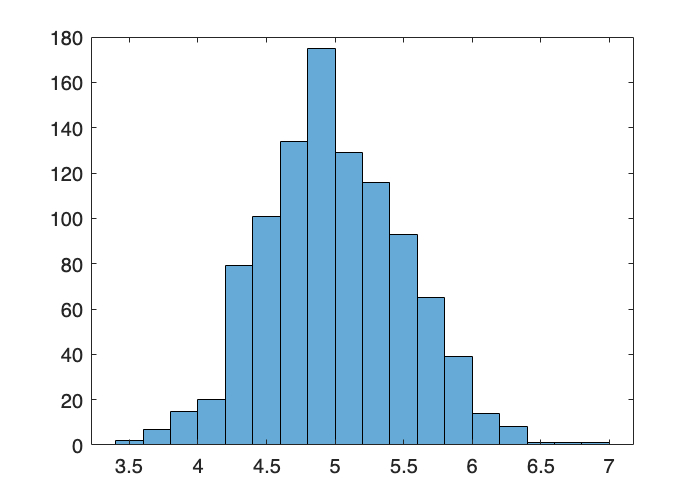

% generate 1000 data sets, each of size 50, calculate the slope of each estimated line and store in a vector.
sizeDataSet=50;
numberDataSets=1000;
slopeStar=zeros(numberDataSets, 1);
%define beta values
betaNot=3;
betaOne=5;
%populate the vector of slopes by generating multiple datasets, calculating the line of best fit, and saving the slope.
for k=1:numberDataSets
    % generate new dataset, just as before
    %obtain noise terms
    epsilonSample=randn(sizeDataSet,1);
    %obtain x-values
    xSample=rand(sizeDataSet, 1);
    %obtain y-values: y=beta_0 + beta_1 x + noise
    ySample=betaNot+betaOne*xSample + epsilonSample;

    % estimate parameters from least squares
    %reminder: polyfit will return estimates in this order: beta_1 beta_0
    hatBeta = polyfit(xSample, ySample, 1);
    slopeStar(k)=hatBeta(1);
end

% now plot a histogram of the means
figure
set(gcf,'units','points','position',[x0,y0,width,height])
histogram(slopeStar)


display(sprintf('mean of slopeStar=%.4g', mean(slopeStar)))

mean of slopeStar=4.994



display(sprintf('standard deviation of slopeStar=%.4g', std(slopeStar)))

standard deviation of slopeStar=0.507


Here we see that the estimates for the slope of the least squares line have a histogram that looks like it could have plausibly been generated from a normal distribution, centered around the true slope.  The histogram also yields an estimate of the *standard error* of the slope estimates.  While in this simple case we could have easily derived the standard error theoretically, it is very easy to do so through simulation.  Further, there are some instances where the standard error is diffucult to come  by theoretically, and so simulation is a critical tool. 

**TASK: What happens as sample size increases or decreases (e.g. sizeDataSet=15, 100, 250, 500, 1000)? .  What happens if the errors are not normally distributed (say, if they are uniform with min -.5 and max .5)?  **

**ADVANCED QUESTION: What happens to the variability of the empirical mean as the number of simulated datasets (numberDataSets) increases?**

So far we have used simulation to show that estimates of statistics of interest are inherently variable across datasets.  In practice, however, we only collect *one *dataset, but we still want to quantify the variability of our estimate.  It turns out that the simulation procedure from above is still useful to us.

## The bootstrap helps us to quantify the SE for a statistic of interest.

In the section above we empirically showed the validity of some theoretical claims, though we relied on both knowlege of the probability distribution- and knowlege of its parameters- in order to generate multiple datasets.  In practice, we may be willing to assume that a certain probability distribution could have reasonably generated our data, though we certainly don't know the true parameters of that distribution.  In order to understand the variability of an estimate of a statistic, however, we can still use the framework developed above.  Specifically our new procedure, the **parametric bootstrap**, is

- Estimate the parameters of the assumed probability distribution using our dataset and the maximum likelihood estimation procedure.

- Generate multiple datasets (*pseudo-data*) from the assumed distribution, plugging in the parameter estimates in place of their theoretical quantities.

- Calculate the statistic of interest for each dataset, and collect them in a vector (say tStar)

- Estimate the SE by calculating the standard deviation of the entries of tStar.

## The nonparametric bootstrap helps us to quantify the SE for a statistic of interest when our distribution is unknown or highly complex.

The general procedure for the nonparametric bootstrap is essentially the same as before.  The steps are

- Generate multiple datasets (*pseudo-data*)

- Calculate the statistic of interest for each dataset and collect the statistics

- Estimate the SE by calculating the standard deviation of the statistics.

The only question that remains is how to generate our pseudo-data.  We do this by *bootstrap sampling *(or *sampling with replacement*) from our actual dataset.

Let's practice the nonparametric bootstrap with a PSTH.  Here our dataset consists of stimulus-locked trials, where each trial is represented by a vector with entries representing the number of spikes in the respective 50ms bin.  Let ${\bf x_i}$be the vector of spike counts for the $i^\mathrm{th}$ trial, then we can calculate the PSTH as


$$\widehat \mathrm{PSTH} = \frac{\sum {\bf x_i}}{N*.05}$$


where N is the total number of trials.

## **TASK: From the StevensonV2 dataset, plot the smoothed PSTH for neuron 193 and target location [0.0706 -0.0709].  Provide 95% confidence bands for the PSTH obtained through the nonparametric bootstrap.  Finally, from the smoothed PSTH, estimate the location of the maximal firing rate in the PSTH.  From your bootstrapped samples, obtain the bootstrapped histogram of the maximal firing rate location.**

The bootstrap procedure is:

- Generate multiple (say, 1000) datasets (*pseudo-data*) by obtaining a bootstrap sample from the original dataset

- Calculate the statistic of interest for each dataset (here it will be the smoothed PSTH)

- In the simulation above we stored the statistic of interest (the mean) for each dataset in a vector called meanStar.  In this case, each psuedo-dataset will generate a PSTH, which we will store as a row vector in a matrix called psthStar.

- Smooth each bootstrapped PSTH.  For now, we can simply smooth each PSTH with a Gaussian filter.  Set the window witdth to 5.

- To obtain the 95% confidence interval we can sort each column independently and record the 25th and 975th entries for each column (assuming we are generating 1000 bootsrapped datasets).  Plot these confidence bands.

- Calculate the location of the maximal firing rate for each bootstrapped dataset.

- Plot the distribution of maximal firing rate locations.

For your convenience, a dataset for neuron 193 and target location [0.0706 -0.0709] is generated in the code below.  To play around with a different neuron or location, simply change the variables "neuron" and "targetInterest".  The variable you will use from this section is "trialMat" which collects the trials along the rows.

***************************************************************************************

**ADVANCED TASK:**

**Question: ** What happens to a bootstrapped estimate of the standard error (as compared to the theoretically derived standard error) as the *sample size* (not the number of bootstrapped datasets) increases?  You can test your answer as follows:

- *Sample a dataset of some sample size from a known distribution* (say, a normal distribution)

- For several different sample sizes ( say, sizeDataSet=15, 50, 100, 150, 300, 500, 1000, 10000, 100000), and for some statistic (for instance the mean), do the following: 

- Calculate the theoretical SE for the given sample size (you can also calculate this by simulation as we did above, though keep this simulation distinct from your original dataset)

- Perform a nonparametric bootstrap on your original dataset

- Compare the bootstrap SE and the theoretical SE.

****************************************************************************************

% load the data (this may already be done, but is included in this file for completeness.
load('StevensonV2.mat')

Error using load
Unable to find file or directory 'StevensonV2.mat'.


% set the neuron and target location of interest
neuron=193;
targetInterest=[0.0706 -0.0709];

% define intervals surrounding start bins called trialIntervals.  The matrix
% trialIntervals will contain as many columns as trials, and three rows
% where the first row describes the time bin for the start of the PSTH, 
% the second row describes the time bin for the end of the PSTH, and the 
% third row will (arbitrarily) index the target locations.

% initialize the trialIntervals matrix
numTrials=length(startBins);
trialIntervals=zeros(3, numTrials);

% size of PSTH to left and right of the start bin, not including the start bin
leftWindow=5;
rightWindow=15;
% total size is sum plus 1 for center bin
windowSize=leftWindow+rightWindow+1;

% assign values to matrix inputs.
trialIntervals(1,:)=startBins-leftWindow;
trialIntervals(2,:)=startBins+rightWindow;

% Next for convenience we assign each target location a number
% obtain a set of unique target locations (note that unique cannot take a 'cols' argument)
targetLocations=unique(targets', 'rows');

% assign the appropriate target location index to each target in trialIntervals
for locs=1:size(targetLocations, 1)
    trialIntervals(3, ismember(targets', targetLocations(locs,:), 'rows'))=locs;
end

% tar determines the index for the variable targetLocations.
tar=find(sum((targetLocations(:,1:2)-repmat(targetInterest, size(targetLocations, 1), 1)).^2, 2)<.0002);

% find the windows (the start and stop location) corresponding to tar.
startStopIndexes=find(trialIntervals(3,:)==tar);

%now define and populate a matrix with the relevant trial snippets from the 'spikes' matrix
trialMat=zeros(length(startStopIndexes), windowSize);

for k=1:length(startStopIndexes)
    trialMat(k, :)=spikes(neuron, trialIntervals(1,startStopIndexes(k)):trialIntervals(2,startStopIndexes(k)));
end

% to plot a PSTH (a histogram), we need to define the bin edges and bin counts (here the firing rate, so we will call that variable
%PSTH).
% The beginning of the start bin is defined to be time 0.
binEdges= -(timeBase*leftWindow):timeBase:(timeBase*rightWindow);

% OK to get us started, let's calculate the original PSTH, and smooth it.
PSTH=mean(trialMat)/timeBase;

%Smooth the PSTH.  For now let's do a simple smoother (a gaussian filter) which is simply a convolution.
% define the gaussian vector for our convolution
smoother=gausswin(7);
smoother=smoother/sum(smoother);

% Let's now apply this smoother to our PSTH.
smoothPSTH=conv(PSTH, smoother, 'same');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%OK now you take it from here and run the bootstrap.  We'll define variables numboot, 
%psthStar (in which you collect all of your PSTHs calculated from pseudo-data), and
%smoothPsthStar (in which you collect all of the smoothed psth's from your pseudo-data.
% Since we don't use psthStar after we smooth each PSTH, we technically don't need to 
% create that variable, but perhaps you will want to play around with the unsmoothed PSTHs
% in your spare time.
numboot=1000;
psthStar=zeros(numboot, windowSize);
smoothPsthStar=zeros(size(psthStar));

% now you create the for loop to collect the PSTHs and smoothed PSTHs.
for boot=1:numboot
    % put your code here
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



% sort the columns of the smoothed PSTH.  Note this sorts each column INDEPENDENTLY.
sortedSmoothPsthStar=sort(smoothPsthStar);

% Now plot the smoothed PSTH, along with the confidence intervals.  We'll do this for you.
figure
bar(binEdges, smoothPSTH, 'histc')
title(sprintf('neuron %d, target %.3g %.3g', neuron, targetInterest(1), targetInterest(2)))
hold on
plot(binEdges+timeBase/2, sortedSmoothPsthStar(floor(numboot*.025), :), 'r')
plot(binEdges+timeBase/2, sortedSmoothPsthStar(floor(numboot*.975), :), 'r')
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%calculate location and value of the max of the smoothed PSTH
%You can use [M, I]=max(X), where M is the max value, and I is the index of the max value).
%We aren't actually using the max value, though perhaps you can play around with this too, if you have spare time

%Put your code for the max here.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate smoothed max rate and location for each bootstrap sample
% Here, you can use [M, I]=max(X, [], 2) to apply the function 'max' to the rows of a matrix 'X'.

% put your code for the max over the bootstrap samples here.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Now plot a histogram of the bootstrapped max locations.  Add

%put your code for the histogram here.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%